## **Przetwarzanie Sygnałów Cyfrowych**

# Analiza harmoniczna cz. 1

## Jan Rosa 410269 AiR

### Wstęp

Ćwiczenia miały na celu zapoznanie z różnymi postaciami i własnościami szeregu Fouriera

#### Zad 1

 Używajżc polecenia plot, za pomocą zczerwonego kółka oznacz na wykresie punkty zmiany znaku wartości sygnału - wykres umieść w sprawozdaniu.

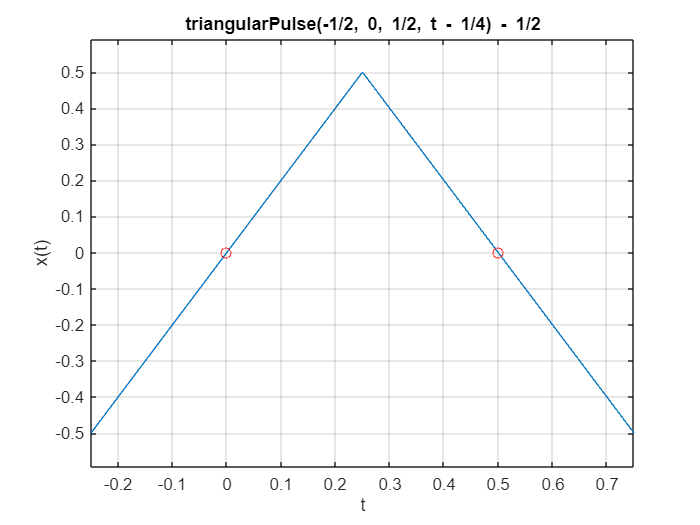

clear all; close all;

syms t t1 t2 offset x 

T0 = 1.0;		% okres
t1 = -0.5; 
t2 = t1+T0;
offset = T0/4;

f0 = 1/T0;		% czestotliwosc
w0 = 2*pi*f0;	% pulsacja

% granice ca³kowania
BND = [t1,t2] + offset; 

x = triangularPulse(t1,0,t2,t-offset)-0.5;
figure; 
ezplot(x,BND); grid on; ylabel('x(t)')
hold on
plot([0, 0.5], 0, 'or')

#### Zad 2

Wyznacz współczynniki zespolonego szeregu Fouriera Xn dla 16-tu pierwszych funkcji

bazowych i oznacz ich wartości na wykresie. W sprawozdaniu umieść uzyskany wykres

zespolonych współcznników szeregu Fouriera.

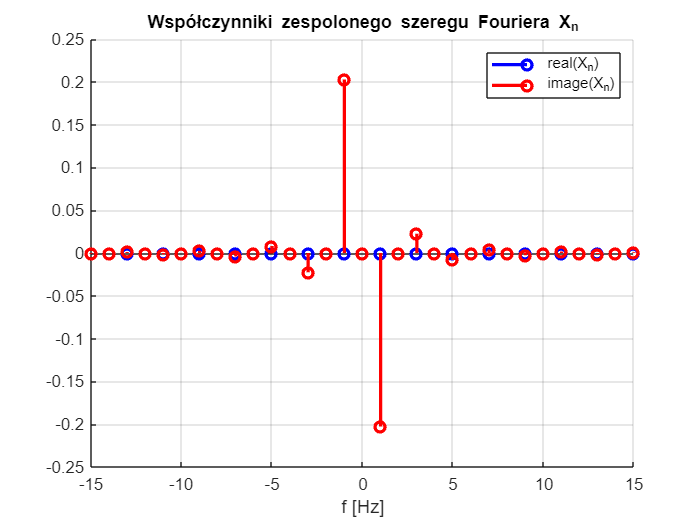

NT = 15;
X=[];
ind = -NT : NT;
for n = ind
    Xn = (1/T0)*int(x*exp(-1i*w0*n*t),t,BND);
    X(n + NT + 1) = Xn;
end
									
figure; hold on; 
stem(ind*f0,real(X),'b','LineWidth',2); 
xlabel('f [Hz]')
stem(ind*f0,imag(X),'r','LineWidth',2); 
grid on
legend('real(X_n)','image(X_n)','Location','NorthEast')
title('Współczynniki zespolonego szeregu Fouriera X_n')
hold off

#### Zad 3

Wyznacz współczynniki an i bn trygonometryczne szeregu dla 15-tu pierwszych częstotliwości harmonicznych oraz składowej stałej a0 zgodnie ze wzorem (5) i przypisz je do wektorów typu rzeczywistego a oraz b. Pokaż je na wykresie z zachowaniem skali częstotliwości 

NT = 0:15;
a=[];
b=[];
bsd=[]
for n = NT
 a(n+1) = (1/T0)*int(x*cos(w0*n*t),t,BND);
 b(n+1) = (1/T0)*int(x*sin(w0*n*t),t,BND);
end

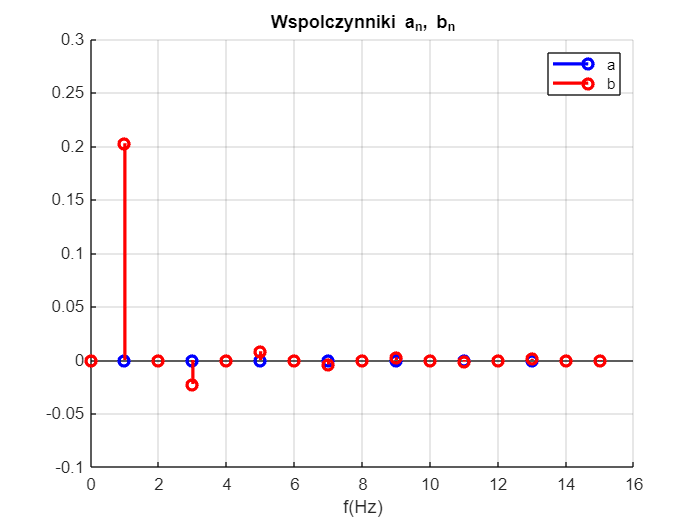

figure();
hold on,
grid on
stem(NT,a,'b','LineWidth',2);
xlabel('n')
stem(NT,b,'r','LineWidth',2);
title('Wspolczynniki a_n, b_n')
xlabel("f(Hz)")
xlim([0 16])
ylim([-0.1 0.3])
legend('a','b')
hold off

#### Zad 4

Na podstawie uzyskanych współczynników a0, an i bn odtwórz 3 okresy przebiegu wejścąiowego w reprezentacji czasowej. 

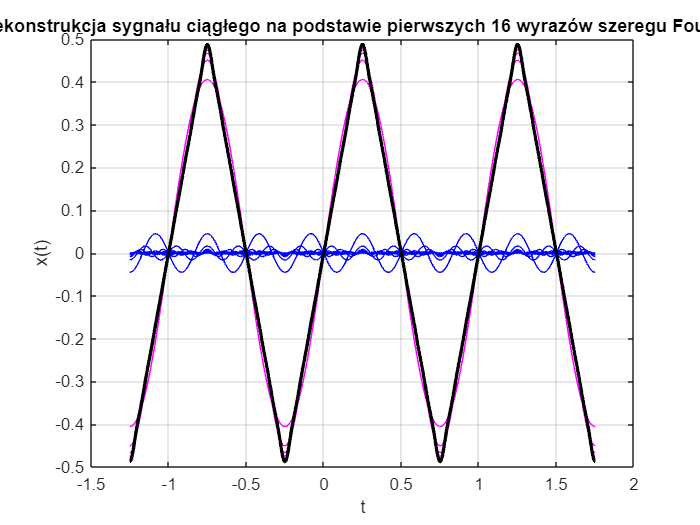

step = (BND(2) - BND(1))/1000;
tt = BND(1)-T0 : step: BND(2) + T0;
xx = zeros(1,length(tt));
xx = xx + a(1); % skladowa stala
figure
plot(tt,xx,'m'); 
grid on; 
hold on;
xlabel('t'); 
ylabel('x(t)');
for n = NT
 xx_n = 2*(a(n+1)*cos(w0*n*tt) + b(n+1)*sin(w0*n*tt));
 xx = xx + xx_n;
 plot(tt,xx_n,'b');
 plot(tt,xx,'m');
 title(sprintf('n = %d',n+1)); 
 %pause(0.1);
 end
plot(tt,xx,'k','LineWidth',2);
title('Rekonstrukcja sygnału ciągłego na podstawie pierwszych 16 wyrazów szeregu Fouriera')
hold off

#### Zad 5

Wyznacz w sposób analityczny wzór (na papierze) na współczynniki szeregu Fouriera wybranego przebiegu (innego niż przebieg sinusoidalny) jego wartość skuteczną oraz współczynnik zniekształceń harmonicznych THD oraz umieśc w sprawozdaniu:

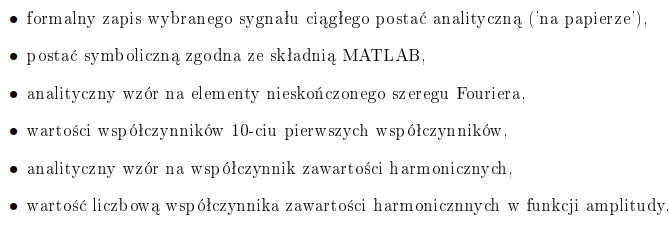

Analitycczny zapis okresu sygnału analitycznie

f(x) = $\left\lbrace \begin{array}{ll}
0\ldotp 5 & x\in \left(0,\frac{T}{2}\right)\\
-0\ldotp 5 & x\not\in \left(\frac{T}{2},T\right)
\end{array}\right.$


$$T=2$$


postać symboliczna okresu sygnału

syms x
func = rectangularPulse(0,1,x) - 0.5

$$func = \mathrm{rectangularPulse}\left(0,1,x\right)-\frac{1}{2}$$

figure
plot([0, 2],[-0.6, 0.6], "w.")
hold on
fplot(func,[0, 2])
title("Okres fali prostokątnej")

Jako że funkcja jest nieparzysta to komponent przy cos będzie równy zero

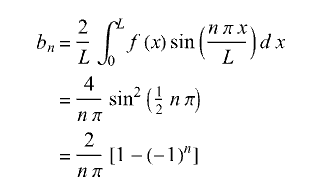

więc dla liczb nieparzystych:

        

Wartości współczynników

Wartości współczynników

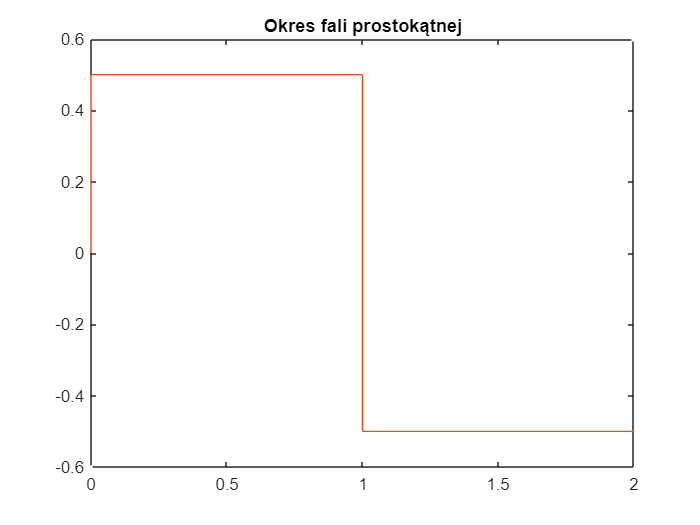

hold off

xx1 = zeros(1,length(tt));
ww0 = pi

ww0 = 3.1416

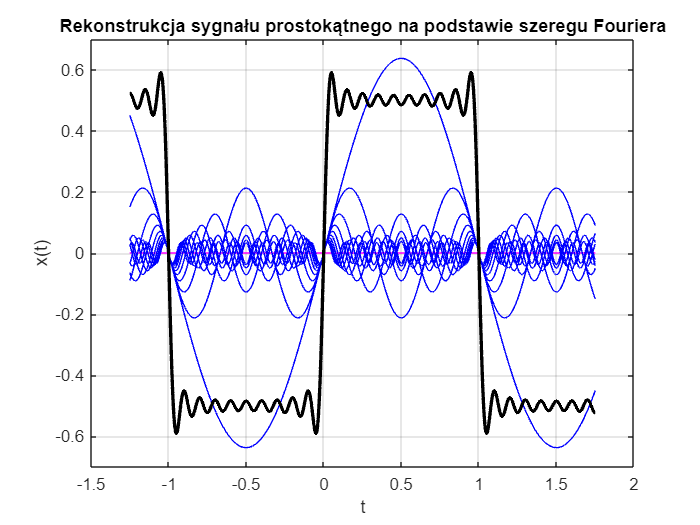

a1 = 1:10;
a1(1) = 0;
xx1 = xx1 + a1(1); % skladowa stala
NT1 = 1:2:20;
figure
plot(tt,xx1,'m'); 
grid on; 
hold on;
ylim([-0.7, 0.7])
xlabel('t'); 
ylabel('x(t)');
for n = NT1
    a1(n) = 1/(n * pi);
    xx_n1 = 2*(a1(n) * sin(ww0*n*tt));
    xx1 = xx1 + xx_n1;
    plot(tt,xx_n1,'b');
    %plot(tt,xx1,'m');
    title(sprintf('n = %d',n+1)); 
    %pause(0.1);
end
plot(tt,xx1,'k','LineWidth',2);
title('Rekonstrukcja sygnału prostokątnego na podstawie szeregu Fouriera')
hold off

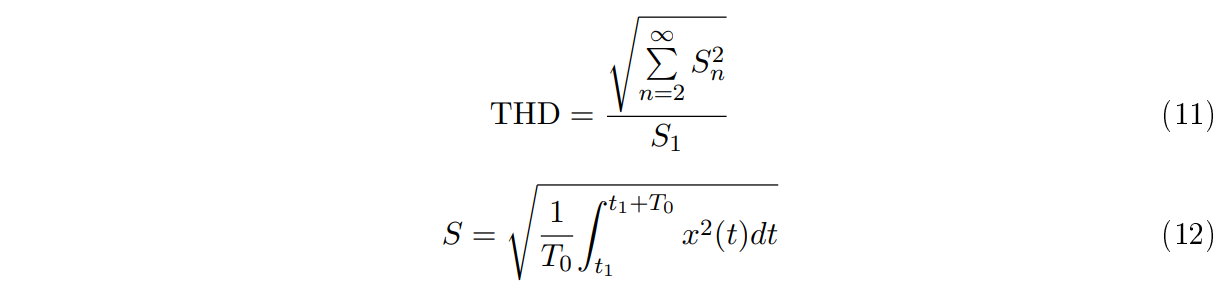

Dla $f_n \left(t\right)=\sin \left(x\right)$:


$$S_n =\frac{a_n }{\sqrt{2}}$$



$$\textrm{THD}=\frac{\sqrt{\sum_{n=2}^{\infty } a_n^2 }}{a_1 }$$


Dla pierwszych 10 składowych:

THD_sum = 0;
for n = NT1(2:end)
    THD_sum = THD_sum + (a1(n))^2;
end
THD=sqrt(THD_sum)/a1(1)

THD = 0.4569

$\textrm{THD}=0\ldotp 4569$ co jest dość blisko wartości dla fali prostokątne gdzie $\textrm{THD}=0\ldotp 48$

### Wnioski

Cwiczenie pozwoliło zapoznać się z szeregami Fouriera w róznych postaciach oraz z współczynnikami z niego wynikającymi